## Spring-mass-damper control system

Antti Paasi

This is a training project with the intention of creating a transfer function system model from scratch. A controller is designed to keep the system oscillating according to an input sinewave despite disturbances.    

Consider a spring-mass-damper system with a driving force. The system can be described as


$$m\;\ddot{x} =-k\;x-c\;\dot{x} +u$$


Laplace transform of the system assuming initial states are zero


$$m\;\;s^2 \;X\left(s\right)=-k\;X\left(s\right)-c\;s\;X\left(s\right)+U\left(s\right)$$


Transfer function $P\left(s\right)=\frac{X\left(s\right)}{U\left(s\right)}$


$$P\left(s\right)=\frac{1}{m\;s^2 +c\;s+k}$$


For a critically damped system, damping coefficient $\zeta =\frac{c}{2\;m\;\omega_n }=1$ , where $\omega_n =\sqrt{\frac{k}{m}}$

Therefore, $c=2\;m\;\sqrt{\frac{k}{m}}\;$

k = 2100             ;  % N/m
m = 20               ;  % kg
c = 2*m*sqrt(k/m)    ;  % kg/m
P = tf([1], [m,c,k]) ;

## Controller Design

We want to keep the system oscillating in a predefined frequency and amplitude. Assume a disturbing force $W\left(t\right)$ that needs to be compensated with a controller. $W\left(t\right)$ is modeled as a random noise source. As the system's preset value is a sinewave, we will use a PD-controller.

A PD-control can be described in the time domain as


$$u\left(t\right)=k_p +k_d \;\dot{e}$$
 

Laplace transform:


$$U\left(s\right)=k_p E\left(s\right)+k_d \;s\;E\left(s\right)$$


Transfer function $H\left(s\right)=\;\frac{U\left(s\right)}{E\left(s\right)}$:


$$H\left(s\right)=k_p +k_d \;s$$
 

To limit loop gain at high frequencies, let's add a small time constant $T$ 


$$H\left(s\right)=k_p +\frac{k_d s}{T\;s+1}$$
  

Open-loop system transfer function


$$G_o \left(s\right)=H\left(s\right)P\left(s\right)$$
   

Initial guesses for $k_p$ and $k_d$ 

T = 0.5    ;  %  time constant
kp = 1.5 ;    %  proportional gain
kd = 1.5 ;      %  derivative gain

H = tf([kp*T+kd, kp], [T, 1]) ; 
G_o = series(P,H) ;

Open-loop stability is verified with poles

poles_o = pole(G_o)

poles_o =   -10.2470
  -10.2470
   -2.0000


The system is stable. 

Closed-loop transfer function:


$$G_c =\frac{H\;P}{1+H\;P}\;$$


G_c = H*P/(1+H*P) ;

Closed loop stability

poles_c = pole(G_c)

poles_c =  -10.2491 + 0.5111i
 -10.2491 - 0.5111i
 -10.2470 + 0.0000i
 -10.2469 + 0.0000i
  -2.0000 + 0.0000i
  -1.9956 + 0.0000i


Stable as well. 

System characteristics

system_info = stepinfo(G_c)

system_info = struct with fields:
         RiseTime: 0.0840
    TransientTime: 2.4822
     SettlingTime: 2.5224
      SettlingMin: 6.4619e-04
      SettlingMax: 0.0015
        Overshoot: 108.3408
       Undershoot: 0
             Peak: 0.0015
         PeakTime: 0.3820


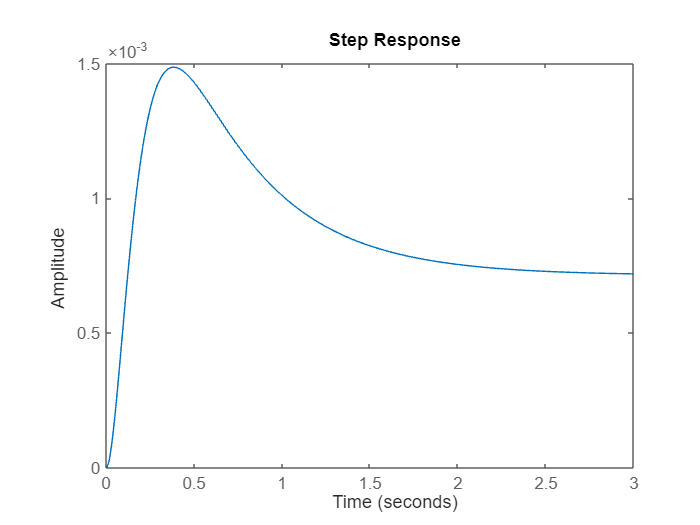

step(G_c)

Seems like the system output amplitude is very small. This has to be compensated later with gain.

## Simulation model

Let's use our closed-loop system transfer function and create a Simulink model. Add a random noise signal. 

num = G_c.numerator{1,1} ;   % tf numerator
den = G_c.denominator{1,1} ; % tf denominator
A = 25   ;   % input sine wave amplitude

setmax = system_info.SettlingMax ;
gain = A/setmax ;   % additional gain to compensate for bias

Run the simulation in Simulink. Plot input and output data.

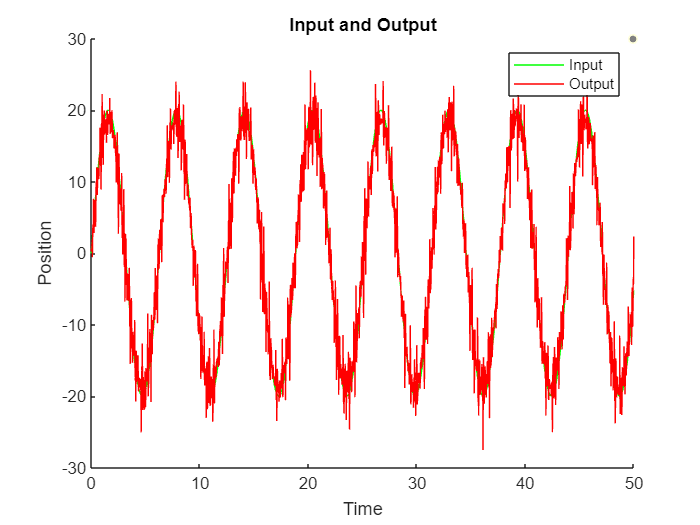

simOut = sim('springmassdamper_sim.slx') ; 
in = simOut.input    ;
out = simOut.output  ;

figure
hold on
title('Input and Output')
xlabel('Time')
ylabel('Position')

plot(in, 'green')
plot(out, 'red')
legend('Input', 'Output')

## Results

With uniform random numbers from -5 to 5 and seed 5 as the noise, the system output is close to set value. Larger range and seed cause more fluctuation in the output.In addition, input amplitude must be considerably larger than the max noise value. 